# Sensing System - revD

Changes since previous version:

- removed SIMULINK model integration as it was very finicky

To-Do's:

- significantly simplify the first step of loading samples into the sensing subsystem itself to be more in line with what will happen on the USRP

- Modify the simulator to be able to run off of a JSON configuration instead of having a function for each piece

## Key parts of the Sensing Subystem

### Debugging Capability

For each debuger array, the format will be as follows:

- 1st column - number of frames computed at that point

- 2nd column - number of chirps computed at that point

- remainder of columns - data taken

## Generate a Spectogram

Steps to generate spectoram:

- reshape into 1us wide windows to sample frequency at (ex: 50 samples per 1us when sampling at 50 Msps)

- reduce the number of samples in the window to the desired size of fft (ex: 32 bits)

- window the sample signal

- perform fft

### Revised Linear Model Computation:

link to resourse used to compute linear model: [https://online.stat.psu.edu/stat462/node/132/](https://online.stat.psu.edu/stat462/node/132/) 

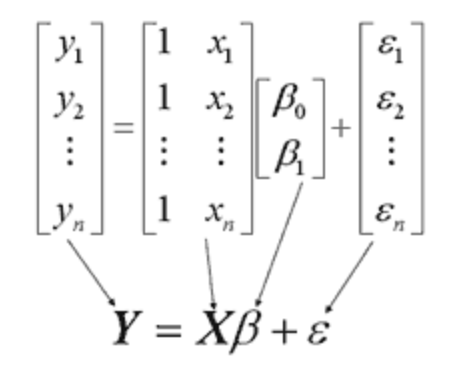

solving for this with out the Epsilon term though


$$\beta = (X^{T}X)^{-1}X^{T}Y$$


## Additional parameter settings for slope and duration

clear;
use_custom_settings = false; %uses the settings below instead of the settings in the config file
slope_MHz_us = 45;
chirp_cycle_period_us = 55;

## Initialize the simulator

simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/BlackBoxRadarAttacks/MATLAB/config_files/";
% file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "1GHz.json";
file_path = "4GHz.json";
simulator.load_params_from_JSON(david_path + file_path);

if use_custom_settings
    %set new parameters for victim
    simulator.Victim.FrequencySlope_MHz_us = slope_MHz_us;
    simulator.Victim.ChirpCycleTime_us = chirp_cycle_period_us;
    simulator.Victim.compute_calculated_vals();

    %set attacker parameters
    simulator.Attacker.Subsystem_tracking.FrequencySlope_MHz_us = slope_MHz_us;
    simulator.Attacker.Subsystem_tracking.ChirpCycleTime_us = chirp_cycle_period_us;
    simulator.Attacker.Subsystem_tracking.compute_calculated_vals();
end

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_radar_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 187.96 MHz/us
	 Idle Time: 			 0.70 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.30 us
	 ADC Samples: 			 4096 
	 ADC Sample Rate: 		 279.90 MSps
	 Ramp End Time: 		 20.94 us
	 Chirp Tx Bandwidth: 		 3935.14 MHz
	 Chirp Sampling Bandwidth: 	 2750.57 MHz
	 ADC Sampling Period: 		 14.63 us
	 Chirp Cycle Time: 		 21.63 us
	 Chirp Wavelength: 		 3.89 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 33.34 ms
	 Active Frame Time 		 5.54 ms
Performance Specifications
	 Max Range 			 223.22 m
	 Range Resolution 		 0.05 m
	 Max Velocity 			 44.99 m/s
	 Velocity Resolution 		 0.35 m/s
FMCW Specifications
	 FMCW sampling rate 		 4198.50 MHz
	 Downsampling factor 		 15
	 Sweep time 			 20.94 us
	 Samples per chirp 		 90825.00 
CFAR Detection Region
	 Range Detection Region 		 0.218 m to 222.945 m
	 Velocity Detection Region 		 -42.885 m/s to 43.237 m/s


## Initialize the Target

target_range = 76;
target_velocity = 15;
simulator.load_target_realistic(target_range,target_velocity);

## Initialize the Victim and Simulation Parameters

%specify the number of frames and chirps to compute
frames_to_compute = 8;

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

%specify whether or not to record a move of the range-doppler plot
record_movie = true;
range_lims = [target_range - 1,target_range + 1.5];
vel_lims = [-1*target_velocity - 7,-1 * target_velocity + 7];
vel_exclusion_region = [-0.1,0.1];
frame_period_ms = simulator.Victim.FramePeriodicity_ms;



simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute, ...
    record_movie,range_lims,vel_lims,vel_exclusion_region);

## Initialize the Attacker

%initialize the attacker parameters
simulator.Attacker.initialize_attacker(...
                        simulator.Victim.FMCW_sampling_rate_Hz * 1e-6,...
                        simulator.Victim.StartFrequency_GHz,...
                        simulator.Victim.Chirp_Tx_Bandwidth_MHz);

%initialize the sensing subsystem's debugger
simulator.Attacker.Subsystem_spectrum_sensing.initialize_debugger(0,simulator.Victim,frames_to_compute);
%set to change 1 to zero to disable

% attack_type = "velocity spoof - noisy";
% attack_type = "velocity spoof - similar velocity";
% attack_type = "range spoof - similar slope";
% attack_type = "range spoof - similar slope, velocity spoof - noisy";
% attack_type = "range spoof - similar slope, velocity spoof - similar velocity";
attack_type = "target";
%initialize the attacker
simulator.Attacker.Subsystem_attacking.set_attack_mode(attack_type);


%if it is desired to specify a specific attack location
if attack_type == "target"
    desired_pos = 76;
    desired_vel = -5;
    simulator.Attacker.Subsystem_attacking.set_desired_attack_location(desired_pos,desired_vel);
end

## Rewritten Attacker Code

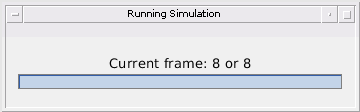

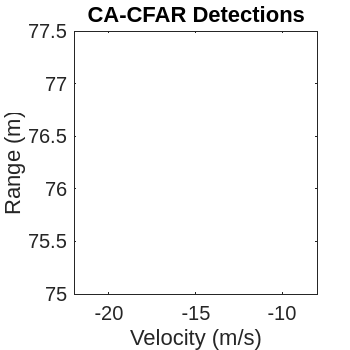

simulator.run_simulation_with_attack(frames_to_compute,true);

% %print out the relevant information
fprintf("Average Frame Duration: %5.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_frame_duration);

Average Frame Duration: 33336.030 us

fprintf("Average Chirp Duration: %3.3f us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_chirp_duration);

Average Chirp Duration: 21.633 us

fprintf("Average Slope: %1.3f MHz/us",simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.average_slope);

Average Slope: 187.846 MHz/us

%compare the predicted frame start times with the actual frame start times
actual_frame_start_times = (3:frames_to_compute).' * simulator.Victim.FramePeriodicity_ms * 1e3 ... 
                                + simulator.Victim.IdleTime_us;
predicted_start_time_errors = simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.captured_frames(2:...
    simulator.Attacker.Subsystem_spectrum_sensing.frame_tracking.num_captured_frames,7) ...
                                - actual_frame_start_times;

Arrays have incompatible sizes for this operation.

Related documentation



errors_in_range = predicted_start_time_errors * 1e-6 * physconst("LightSpeed");

clf;
plot(predicted_start_time_errors);
title("Timing Estimation error vs Number of Frames")
xlabel("Number of Frames Sensed")
ylabel("error (us)")
y_lim = max(abs(predicted_start_time_errors))
ylim([-y_lim, y_lim])

%add in the axis for range error
yyaxis right
plot(errors_in_range)
ylabel("corresponding range error (m)")
set(gca,"YColor", 'black')
y_lim = max(abs(errors_in_range))
ylim([-y_lim, y_lim])
cla
print('-r300',"generated_plots/estimation_error_over_frames",'-dsvg')
print('-r300',"generated_plots/estimation_error_over_frames",'-dpng')

## Run the Debugger if enabled

if simulator.Attacker.Subsystem_spectrum_sensing.Debugger.enabled
    simulator.Attacker.Subsystem_spectrum_sensing.debugger_compute_errors(simulator.Victim);
    [summary_table] = simulator.Attacker.Subsystem_spectrum_sensing.debugger_summarize_errors();
    summary_table
end

### Plot Spectrogram and Generated Chirps

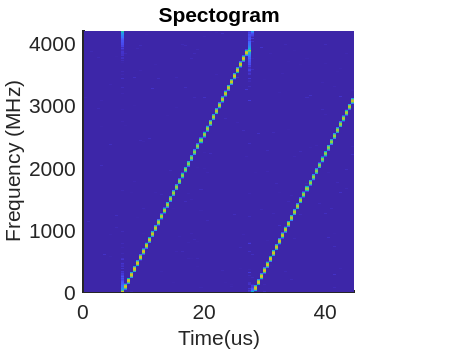

%plot spectrogram
clf;
simulator.Attacker.Subsystem_spectrum_sensing.plot_received_spectogram(45);
print('-r300',"generated_plots/generated_spectrogram",'-dsvg')
print('-r300',"generated_plots/generated_spectrogram",'-dpng')

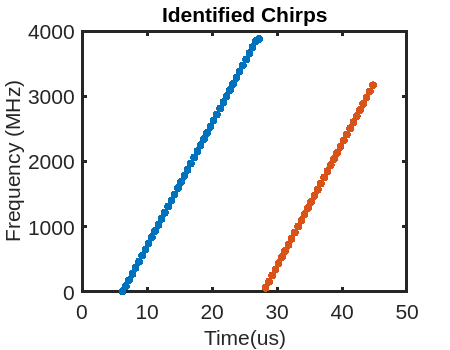

simulator.Attacker.Subsystem_spectrum_sensing.plot_clusters(45);
print('-r300',"generated_plots/identified_chirps",'-dsvg')
print('-r300',"generated_plots/identified_chirps",'-dpng')